clear all;
clc;
close all;

## Leitura de dados

LerDados 

## Tempo

N = length(Entrada);  
T = 10e-3; 
Duracao = N*T;
tempo = linspace(0,Duracao,N);  

## Dados

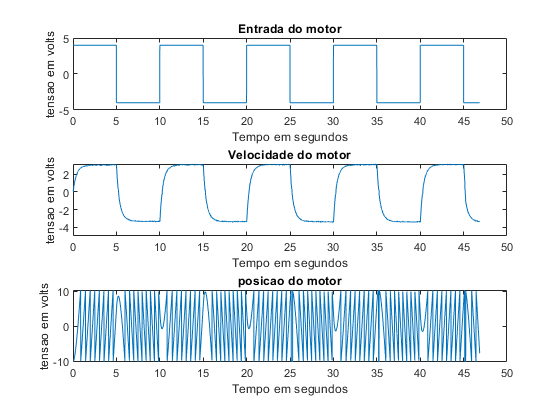

figure(1) 
subplot(3,1,1); plot(tempo,Entrada) 
xlabel('Tempo em segundos')
ylabel('tensao em volts')
title('Entrada do motor')

subplot(3,1,2); plot(tempo,Velocidade) 
xlabel('Tempo em segundos')
ylabel('tensao em volts')
title('Velocidade do motor')

subplot(3,1,3); plot(tempo,Posicao)
xlabel('Tempo em segundos')
ylabel('tensao em volts')
title('posicao do motor')

## Modelo do sistema

% Hipotese : Sistema eh de primeira ordem, a forma canonica:


$$G_{p\;} \left(s\right)=\frac{K}{T_S +1}$$


% desejo determinar o ganho k e aconstante de tempo T
K = 1;      % valor inicial para o ganho
Tt = 1;      % Constante de tempo

Gp = tf(K,[Tt,1])        % funcao de transferencia do modelo


Gp =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.




ym = lsim(Gp, Entrada, tempo);       % simula a saida do modelo

figure(2)

plot(tempo, Velocidade);
hold;

Current plot held


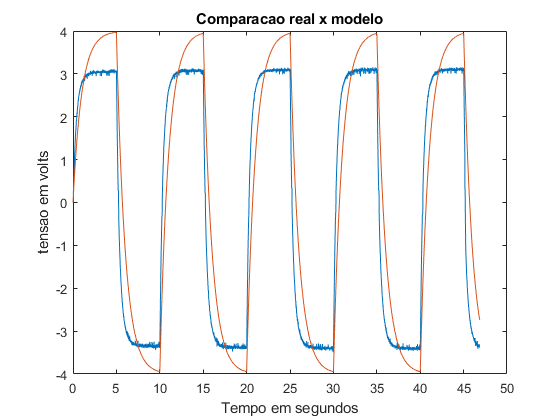

plot(tempo, ym);

xlabel('Tempo em segundos')
ylabel('tensao em volts')
title('Comparacao real x modelo')

## Determinar o ganho K e a constante de tempo visando minimizar o erro

% quando a entrada eh 4 volts, a velocidade corresponde a 3.072
% a velocidade = k * entrada --> k = velocidade/entrada

K = 3.072/4;                % ganho do sistema

Gp = tf(K,[Tt,1])           % funcao de transferencia do modelo


Gp =
 
  0.768
  -----
  s + 1
 
Continuous-time transfer function.




ym = lsim(Gp, Entrada, tempo);       % simula a saida do modelo

figure(3)

plot(tempo, Velocidade);
hold;                       % congela para sobrepor

Current plot held


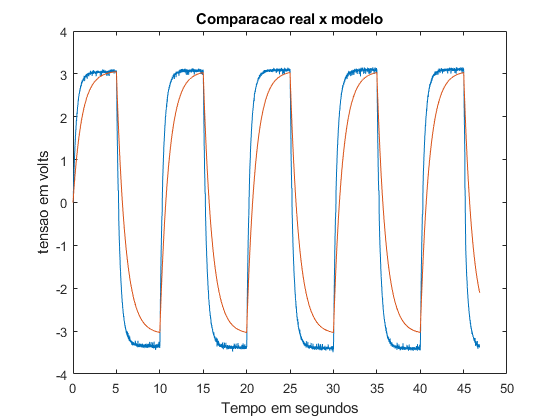

plot(tempo, ym);

xlabel('Tempo em segundos')
ylabel('tensao em volts')
title('Comparacao real x modelo')


% acerto da constante de tempo - T
% criterio de 2% - 4T

limiar = 0.98*3.072     % Momento que atinge 4 constantes de tempo

limiar = 3.0106


Tt = 1.99/4;             % Tempo em q o sinal atinge a 98% ---> 4T

K = 3.072/4;            % ganho do sistema

Gp = tf(K,[Tt,1])        % funcao de transferencia do modelo


Gp =
 
     0.768
  ------------
  0.4975 s + 1
 
Continuous-time transfer function.




ym = lsim(Gp, Entrada, tempo);       % simula a saida do modelo

figure(4)

plot(tempo,Velocidade);
hold;                   % congela para sobrepor

Current plot held


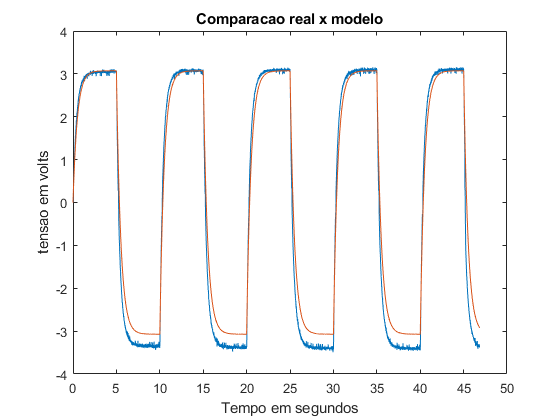

plot(tempo, ym);

xlabel('Tempo em segundos')
ylabel('tensao em volts')
title('Comparacao real x modelo')

hold off;

## 
$$G_{\mathrm{ma}}$$


1. Erro estacionário inferior a 0.25 para rampa unitária. 

2. TsMF < 75%TSM A. 

3. Mp < 15%. 

Analisando o sisotool, a partir da funcao de transferencia Gp(s), adcionamos 1 polo real e 1 zero. Assim chegamos no controlador $G_c \left(s\right)=\frac{7\ldotp 2\left(s+2\ldotp 4\right)}{s}$

syms s 
Gc = tf([7.2 (7.2*2.4)], [1 0])


Gc =
 
  7.2 s + 17.28
  -------------
        s
 
Continuous-time transfer function.



Gma = Gp*Gc


Gma =
 
  5.53 s + 13.27
  --------------
  0.4975 s^2 + s
 
Continuous-time transfer function.




mult = tf([1 0], [1])


mult =
 
  s
 
Continuous-time transfer function.



degrau = tf([1], [1 0])


degrau =
 
  1
  -
  s
 
Continuous-time transfer function.



rampa = tf([1], [1 0 0])


rampa =
 
   1
  ---
  s^2
 
Continuous-time transfer function.




erro_degrau = mult*(1/(1+Gma))*degrau


erro_degrau =
 
         0.4975 s^3 + s^2
  -------------------------------
  0.4975 s^3 + 6.53 s^2 + 13.27 s
 
Continuous-time transfer function.



erro_degrau_num = (0.5*s^3 + s^2)/(0.5*s^3 + 6.53*s^2 + 13.27*s);
limit(erro_degrau_num, s, 0)

$$ans = 0$$

Chegamos em um erro zero para o degrau e agoara testaremos com a rampa como entrada esperando para tal um erro menor que 25%


$${\mathrm{lim}}_{s\to 0} \;s*\mathrm{erro}<0\ldotp 25$$


erro_rampa = mult*(1/(1+Gma))*rampa


erro_rampa =
 
          0.4975 s^3 + s^2
  ---------------------------------
  0.4975 s^4 + 6.53 s^3 + 13.27 s^2
 
Continuous-time transfer function.



erro_rampa_num = (0.4975*s^3 + s^2)/(0.4975*s^4 + 6.53*s^3 + 13.27*s^2);
limit(erro_rampa_num,s,0)

$$ans = \frac{100}{1327}$$

Chegamos em um erro de 0.07 para rampa utilizando este controlador.

## Malha fechada

Utilizamos o ganho em malha fechada, para plotar os testes com o degrau e rampa, para comprovar que suprimos as necessidades

Gmf = feedback(Gma,1)


Gmf =
 
        5.53 s + 13.27
  ---------------------------
  0.4975 s^2 + 6.53 s + 13.27
 
Continuous-time transfer function.



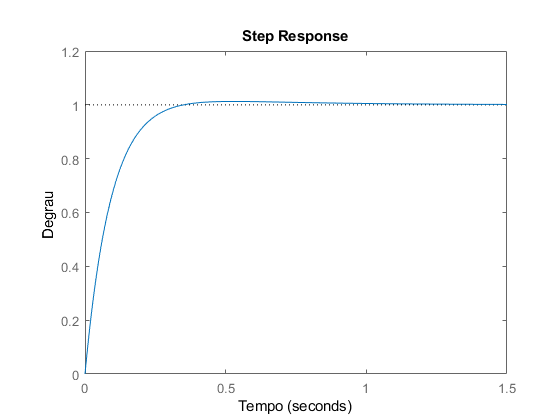

figure(5)
step(Gmf);
xlabel('Tempo')
ylabel('Amplitude')
ylabel('Degrau')

yms = lsim(Gmf, tempo, tempo);

figure(6)
plot(tempo, yms);
hold; plot(tempo,tempo);

Current plot held


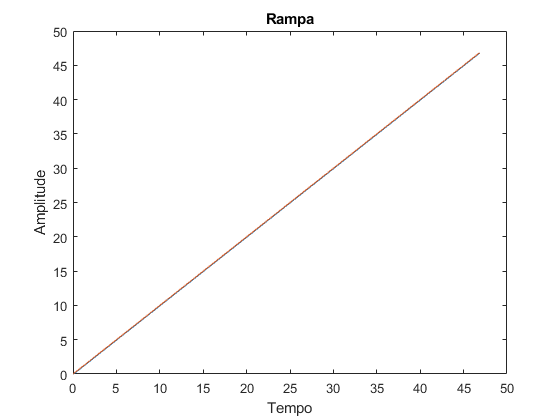

xlabel('Tempo')
ylabel('Amplitude')
title('Rampa')

Suprimos com esse controlador todos os requisitos pedidos, obtivemos um Settling time de  0.29 segundos em malha fechada, tivemos um erro menor do que 15% para a ramp com entrada além de um overshoot de 1.12%

## Transformar G(s) por G(z)

Gcz = c2d(Gc, Tt) % Transformando Gc(s) para Gc(z)


Gcz =
 
  7.2 z + 1.397
  -------------
      z - 1
 
Sample time: 0.4975 seconds
Discrete-time transfer function.




Gpz = c2d(Gp, Tt) % Transformando Gp(s) para Gp(z)


Gpz =
 
    0.4855
  ----------
  z - 0.3679
 
Sample time: 0.4975 seconds
Discrete-time transfer function.



## Modelo da malha de posicao

1. Erro estacionário inferior a 0.25 para rampa unitária. 

2. TsMF < 75%TsMA. 

3. Mp < 15%. 

Gint = tf([1],[1 0]);    
Gpos = Gint*Gp


Gpos =
 
      0.768
  --------------
  0.4975 s^2 + s
 
Continuous-time transfer function.




ypos = lsim(Gpos, Entrada, tempo)

ypos =          0
    0.0003
    0.0012
    0.0027
    0.0048
    0.0075
    0.0107
    0.0144
    0.0187
    0.0236


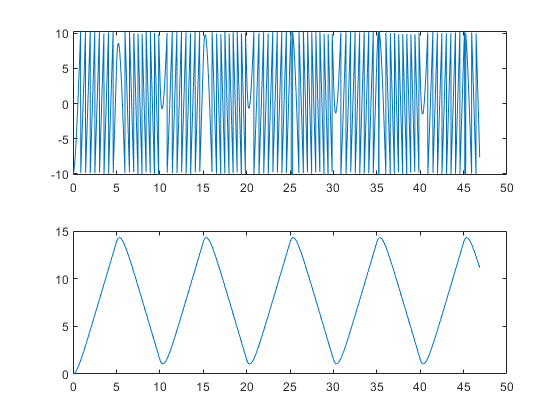


figure(7)

subplot(2,1,1);plot(tempo,Posicao);

subplot(2,1,2);plot(tempo,ypos);

## 
$$G_{\mathrm{mapos}}$$


Analisando o sisotool, a partir da funcao de transferencia Gp(s), adcionamos 1 polo real e 1 zero. Assim chegamos no controlador $G_c \left(s\right)=\frac{768\ldotp 16\left(s+3\ldotp 915\right)}{\left(s+44\ldotp 22\right)}$

syms s 
Gcp = tf([768.16 (768.16*2.4)], [1 44.22])


Gcp =
 
  768.2 s + 1844
  --------------
    s + 44.22
 
Continuous-time transfer function.



Gmap = Gpos*Gcp


Gmap =
 
         589.9 s + 1416
  -----------------------------
  0.4975 s^3 + 23 s^2 + 44.22 s
 
Continuous-time transfer function.




$$\lim_{s\to 0} \;s*\textrm{erro}<0\ldotp 25$$


mult = tf([1 0], [1])


mult =
 
  s
 
Continuous-time transfer function.



rampa = tf([1], [1 0 0])


rampa =
 
   1
  ---
  s^2
 
Continuous-time transfer function.



erro_rampa = mult*(1/(1+Gmap))*rampa


erro_rampa =
 
       0.4975 s^4 + 23 s^3 + 44.22 s^2
  ------------------------------------------
  0.4975 s^5 + 23 s^4 + 634.2 s^3 + 1416 s^2
 
Continuous-time transfer function.



erro_rampa_num = (0.4975*s^4 + 23*s^3 + 44.22*s^2)/(0.4975*s^5 + 23*s^3 + 634.2*s^3 + 1416*s^2);
limit(erro_rampa_num,s,0)

$$ans = \frac{737}{23600}$$

Como podemos ver, o erro estacionario na rampa tem um valor de 0,03 ou 3%, que se encaixa no valor de erro < 25%

## Malha fechada de posição

Utilizamos o ganho em malha fechada, para plotar os testes com o degrau e rampa, para comprovar que suprimos as necessidades

Gmfp = feedback(Gmap,1)


Gmfp =
 
             589.9 s + 1416
  ------------------------------------
  0.4975 s^3 + 23 s^2 + 634.2 s + 1416
 
Continuous-time transfer function.



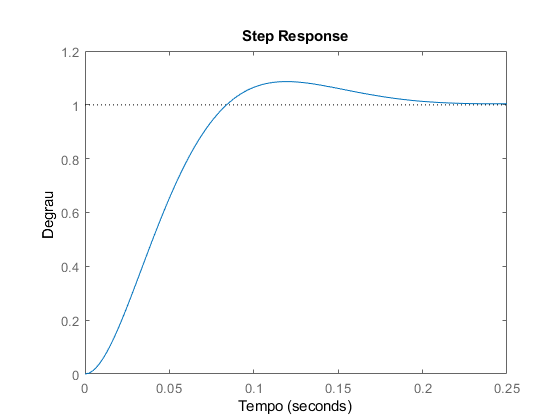

figure(5)
step(Gmfp);
xlabel('Tempo')
ylabel('Amplitude')
ylabel('Degrau')

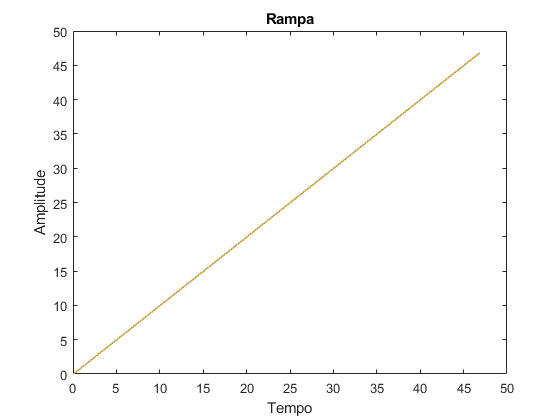

Current plot released


yms = lsim(Gmfp, tempo, tempo);

figure(6)
plot(tempo, yms);
hold; plot(tempo,tempo);

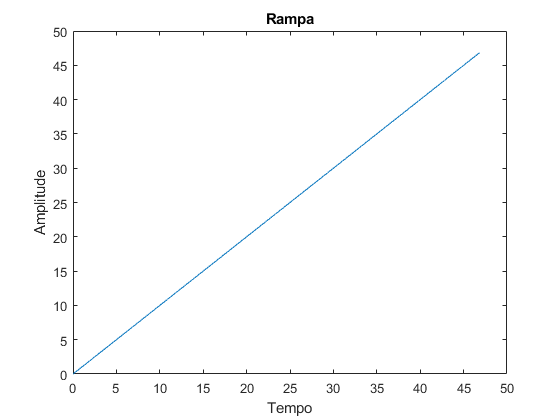

xlabel('Tempo')
ylabel('Amplitude')
title('Rampa')

Suprimos com esse controlador todos os requisitos pedidos, obtivemos um Settling time de  0.29 segundos em malha fechada, tivemos um erro menor do que 15% para a ramp com entrada além de um overshoot de 1.12%

## Transformar G(s) por G(z)

Gcposz = c2d(Gcp, Tt) % Transformando Gcpos(s) para Gcpos(z)


Gcposz =
 
  768.2 z - 726.5
  ---------------
   z - 2.791e-10
 
Sample time: 0.4975 seconds
Discrete-time transfer function.




Gpposz = c2d(Gpos, Tt) % Transformando Gppos(s) para Gppos(z)


Gpposz =
 
     0.1406 z + 0.101
  ----------------------
  z^2 - 1.368 z + 0.3679
 
Sample time: 0.4975 seconds
Discrete-time transfer function.

